% signal temps continu xc(t) de durée T
F0=2

F0 = 2

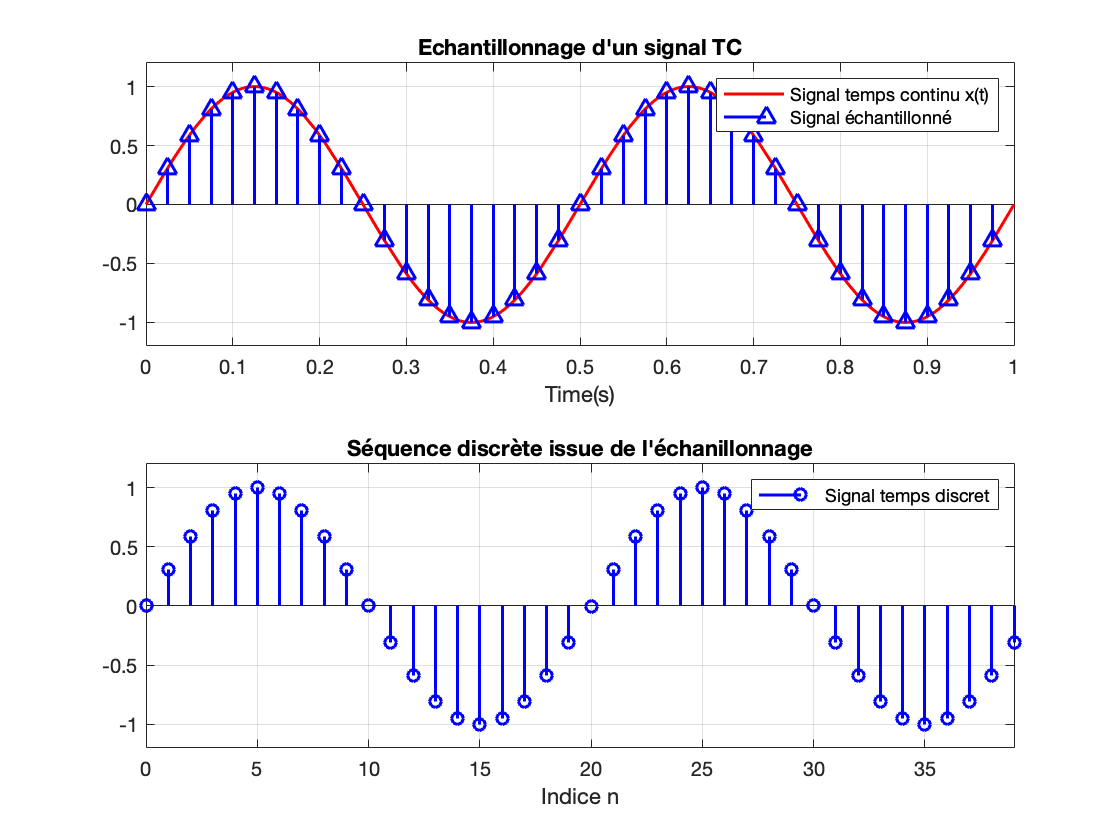

T=1;
syms t      	% symbolic toolbox
xc= (sin(2*pi*F0*t))*rectangularPulse(0,T,t); 		% continuous signal

% paramètre de l’échantillonnage
Fs= 20*F0; % Fs >> 2F0
Ts=1/Fs;  		
N=Fs*T;    				% nombre d’échantillons du signal dans le temps T
n=0:N-1;
td=n*Ts;  				% vecteur de temps d’échantillonnage
sig1d=sin(2*pi*F0*td);  % définition du signal temps discret

tiledlayout(2,1)
nexttile
f=fplot(xc,'r');		% tracé pour un signal défini par la  SymbolicTool
f.LineWidth=1.5;
xlabel("Time(s)")
hold on;
stem(td,sig1d,'b',"lineWidth",1.5,"MarkerSize",8, "Marker",'^')
axis([0 T -1.2 1.2]);grid;
legend("Signal temps continu x(t)","Signal échantillonné")
title("Echantillonnage d'un signal TC");

nexttile
stem(n,sig1d,'b',"lineWidth",1.5 )
axis([0 N-1 -1.2 1.2]);grid;
legend("Signal temps discret")
xlabel("Indice n")
title("Séquence discrète issue de l'échantillonnage");